In this experiment, Inferior Temporal(IT) multi-unit neural outputs are predicted using Deep Neural Network(DNN) softmax outputs and V4 outputs using ridge regression.

The purpose of this experiment is to show that reliability of DNN predictions of IT is comparable to that of V4 predictions.

To show this, data from Cadieu et al. 2014 is used for the experiment. Here are links to the data:

[Neural representation](https://s3.amazonaws.com/cadieu-etal-ploscb2014/PLoSCB2014_data_20141216.zip)

[Model representation](https://s3.amazonaws.com/cadieu-etal-ploscb2014/PLoSCB2014_models_20150218.zip)

The data is pre-downloaded in this folder.

In the Cadieu et al. 2014 paper, 1960 images were shown to the primate. IT multi-unit responses for each image has 168 channels. Hence, data for IT multiunits is a 1960x168 matrix.

Some string arguments used in functions for:

**Neural representation data:**

V4 multiunits=*'V4'*

IT multiunits=*'IT'*

**Model representation data:**

V1 like=*'V1'*

V2 like=*'V2'*

HMO=*'HMO'*

HMAX=*'HMAX'*

Krizhevsky et al. 2012=*'Kr'*

Zeiler & Fergus 2013=*'Ze'*

**Reliability**

Using V4 or a DNN feature matrix, each of the 168 channels are predicted using ridge regression. There are ten train/test splits of 70:30, as specified by the meta of the data matrices. Moreover, optimum alpha of ridge regression is determined through three-fold cross-validation on train set. The formula used for ridge regression is:


$$\text{ }\theta ={\left(\mathrm{x'}\ldotp x+\mathrm{G'}\ldotp G\right)}^{-1} \ldotp \mathrm{x'y}$$


where $G=\alpha ∗I_{a\times a}$

where **a **is the number of features of the feature matrix. 

The ridge regression function is *ridge_r.*

After cross-validation, ridge regression is done again on train set using optimum alpha. After p-hat on test set is calculated, it is split into half and Pearson correlation is calcuated between them and their corresponding p values. The mean Pearson correlation between them is calculated to obtain split-half Spearman correlation using this formula:


$$r_{\mathrm{Sp}} =\frac{\left(2∗{\overset{-}{r} }_{\mathrm{Pe}} \right)}{\left(1+{\overset{-}{r} }_{\mathrm{Pe}} \right)}$$


Explained explainable variance is calculated by multiplying Spearman correlation with 100. To represent individual channel, median value is obtained from ten train test splits. This is done for all the channels. To represent a model, the mean explained explainable variance of the 168 channels is taken. The explained variance is the variance of the 168 Spearman correlations times 100.

The lines of code below will calculate such values for HMO, HMAX, V4, Krizhevsky et al. 2012 and Zeiler & Fergus 2013. These results are stored in files with '_model.mat' suffix. **They should only be run on the terminal of openmind.**

squeue slurm HMO;
squeue slurm HMAX;
squeue slurm Kr;
squeue slurm Ze;
squeue slurm V4;

Here is a bar chart of the results:

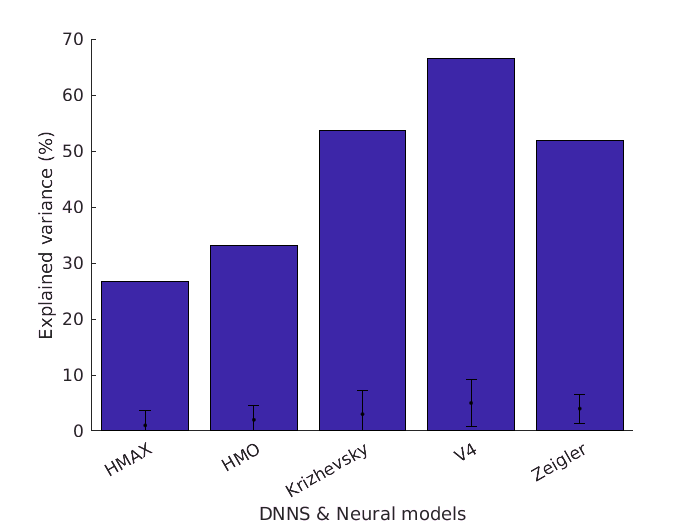

path_suff='_model.mat';
data_arr=categorical({'HMAX','HMO','Kr','Ze','V4'});
data_arr_2=categorical({'HMAX','HMO','Krizhevsky et al. 2012','Zeiler & Fergus 2013','V4'});
exp_var_arr=zeros(1,5);
variance=zeros(1,5);
matrix=zeros(5,168);
for i=1:size(exp_var_arr,2)
    m=load([char(data_arr(i)) path_suff]);
    exp_var_arr(i)=m.exp_var;
    variance(i)=m.var;
end
figure
hold on
bar(data_arr_2,exp_var_arr)
errorbar(data_arr_2,variance,'.','Color','black')
ylabel('Explained variance (%)')
xlabel('DNNS & Neural models')
ax=gca;
ax.YLim=[0 70];
saveas(gcf,'barplot.png');

The error bars represent explained variance, whereas the barplot represents the explained explainable variance. As can be seen, results of Krizhevsky et al. and Zeiler & Fergus are comparable to that of V4.

Here is a scatter plot of 168 points representing the IT multi unit channels, comparing results of V4 and Zeiler & Fergus.

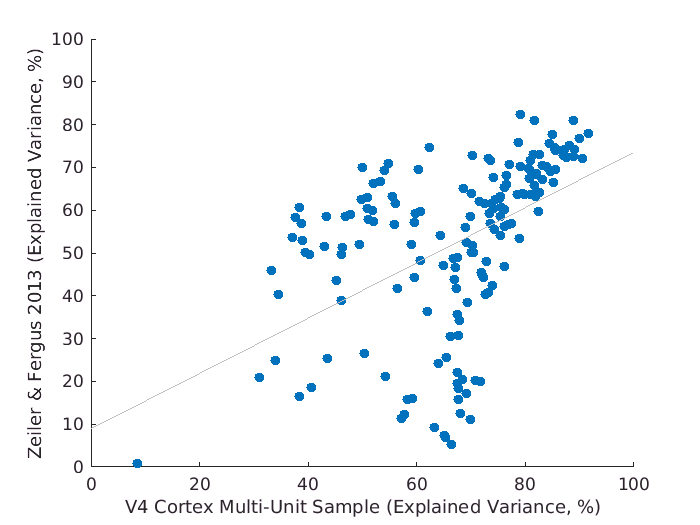

matrix=zeros(5,168);
for i=1:size(exp_var_arr,2)
    m=load([char(data_arr(i)) path_suff]);
    matrix(i,:)=m.arr;
end
figure 
hold on
ze=matrix(end-1,:);
v4=matrix(end,:);
scatter(v4,ze,'filled')
ax=gca;

ax.YLim=[0 100];
ax.XLim=[0 100];
xlabel('V4 Cortex Multi-Unit Sample (Explained Variance, %)')
ylabel('Zeiler & Fergus 2013 (Explained Variance, %)')
lsline
saveas(gcf,'lineplot.png')


r=corrcoef(ze,v4);
disp(['r=' num2str(r(1,2))])

r=0.50379


The Pearson correlation coefficient of the scatter plot is, as can be seen, 0.50379.

In order to see how similar representations of objects are to each other in neural models, DNNs and IT outputs predicted from DNNs, Representational dissimilarity matrices(RDMs) were calculated. They are 49x49 each. They are calculated using this formula:


$${\mathrm{RDM}\left(\phi \left(x\right)\right)}_{\mathrm{ij}} =1\frac{\mathrm{cov}\left(\phi \left(x_i \right),\phi \left(x_j \right)\right)}{\sqrt{\mathrm{var}\left(\phi \left(x_i \right)\right)\ldotp \mathrm{var}\left(\phi \left(x_j \right)\right)}}$$


where *i* and *j* are rows of the feature matrix.

Seven categories of images were shown to the primate; animals, cars, chairs, faces, fruits, planes, tables. Each category has seven subcategories, hence the 49x49 shape.

Since heatmaps are not supported by live script, the codes below will not run here. The RDM images will be saved.

RDM_calc('NM','IT');%For IT cortex

Error using heatmap (line 82)
Adding HeatmapChart to axes is not supported. Turn hold off.

Error in RDM_calc (line 42)
h=heatmap(RDM,'ColorLimits',[0 1],'Colormap',color_map);

RDM_calc('NM','V4');%For V4 cortex

The RDMS calculated with functions above will be saved with  '_Neural Representations.png' suffix.

RDM_calc('DNN','HMO');%For HMO
RDM_calc('DNN','Kr');%For Krizhevsky et al. 2012
RDM_calc('DNN', 'Ze');%For Zeiler & Fergus 2013

The RDMS calculated with functions above will be saved with  '_Model Representations.png' suffix and '_Model Representations + IT-fit.png'.

The RDM_calc function takes in two arguments, data type and neural/model representation name.

Two valid argument values are:

Neural model=*'NM'*

Deep Neural Network=*'DNN'*

To obtain RDMs of IT outputs predicted by HMO, Krizhevsky et al. and Zeiler & Fergus, *IT_predictor *function is used*. *It takes in arguments the same way as RDM_calc does. It predicts IT outputs the same way as *IT_multi *does, but there is only one train/test split of 70:30. 

**Generating DNN codes of images**

In order to evaluate DNNs, a package called *matconvnet* is used. This is the [link](http://www.vlfeat.org/matconvnet/download/matconvnet-1.0-beta24.tar.gz).

After downloading, unzipping the package and getting into package directory, these lines should be run:

mex -setup;
addpath matlab;
vl_compilenn;

This should be done everytime matlab is started in order to use this package.

These lines of code will generate DNN code, which is a 4096-dimensional output 

of the final fully-connected layer of pretrained AlexNet model. This is the [link](http://www.vlfeat.org/matconvnet/models/imagenet-caffe-alex.mat) to download the model. It should be kept in the same directory as this script.

net=load('alexnet-caffe');%loading Alexnet
net=vl_simplenn_tidy(net);%Replacing empty values in Alexnet model with zero
fcn_shape=net.layers{end-1}.size(3);% Feature count of final fully connected layer 
img_norm_meta=net.meta.normalization;%AlexNet meta
if ~exist('imdb.mat','file')
    image_database(img_norm_meta.imageSize(1),net.meta.normalization.averageImage);%Creating matrix of all input images
end
data=load('imdb.mat');%LOading input image database
net.layers=net.layers(1:end-2);%Keeping model until last fully connected layer
feat=vl_simplenn(net,data.images.data);%Calculating DNN code of input images
a=squeeze(feat(end).x).';
save('AlexNet2012','a');%Saving DNN code

*imdb.mat *creates a database of input images, which are 227x227x3 center crops of the images. Mean image of pretrained model is subtracted from each image matrix.